# **Norma IEEE-754**

El año 1985, Institute for Electrical and Electronic Engineers (IEEE) publicó el informe Binary Floating Point Arithmetic Standard 754 − 1985, en el que se especifican normas para representar números en punto flotante con precisión simple doble y formatos de precisión extendidos. El año 2008 fue publicada el IEE Std 754-2008. 

La norma IEEE-754 define:

- Formatos aritméticos: conjuntos de datos de punto flotante binarios y decimales, que consisten en números finitos, incluidos los ceros con singo, y los números desnormalizados, infinitos y valores especiales "no numéricos" (Nan).

- Formatos de intercambio: codificaciones (cadenas de bits) que se pueden utilizar para intercambiar datos de punto flotante de forma eficiente y compacta.

- Reglas de redondeo: propiedades que deben satisfacer al redondear los números.

- Operaciones aritméticas.

- Indicaciones de excepciones: overflow, underflow, divisiones por cero...

# **Formatos aritméticos**

## **Single and Double Precision:**

### **Single Precision**

La representación en punto flotante de simple precisión ocupa 1 word(32 digitos), asignando: 1 bit para el signo del número real, 8 bits para el exponente y 23 bits para la mantisa. 

Un nombre real x en simple precisión se representa de la siguiente manera:

              

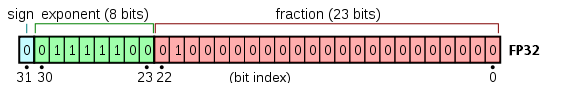

Donde **s** es el valor del signo. **c** es el valor del exponente (con signo).   el valor de la mantisa. 

Los valores de los exponentes con todo 0's o todo 1's, están reservados. 

### **Denormal number (Single Precision)**

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los números normalizados, es decir, s es el valor del signo y    el valor de la mantisa. El valor del exponente no se utiliza.

### **Double Precision**

La representación en punto flotante con doble precisión ocupa 2 words(64 digitos), asignando: 1 bit para el signo del número real, 11 bits para el exponente y 52 bits para la mantisa.

Un nombre real x en simple precisión se representa de la siguiente manera:

            

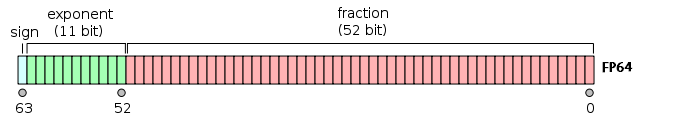

Donde **s** es el valor del  signo. **c** es el valor del exponente (con signo).  el valor de la mantisa.

Los valores de los exponentes con todo 0's o todo 1's, están reservados. 

### **Denormal number (Double Precision)**

Si el exponente es 0 y la mantisa diferente de 0. 

En caso de que el exponente sea 0 y la mantisa sea distinto a 0 entonces representa un "Denormal number". Siguen usando el mismo criterio que los números normalizados, es decir, s es el valor del signo y    el valor de la mantisa. El valor del exponente no se utiliza.

### Inf

Si el exponente es todos 1 y la mantisa es 0 representa a los números infinitos. En caso de que el signo sea 0 respresenta el +infinito.En caso de que el signo sea 1 representa -infinito.

x = 1/0

### **Nan(Not-A-Number)**

Si el exponente es todos 1 y la mantisa es diferente de 0 representa Nan(Not-A-Number).  Esto se utiliza para expresar un resultado imposible de calcular (raíces negativas, división por cero...)

x = 0/0

### **Zero**

Si el exponente es todos 0 y la mantisa 0 representa al 0. En caso de que el signo sea 0 representa el +0. En casi de que el signo sea 1 representa -0.

x = 0
format hex
x
x = -0

# Valores particulares

## Epsilon

En la aritmética de coma flotante, el épsilon de la máquina es el menor valor de una determinada máquina que cumple lo siguiente:

1,0 + epsilon > 1,0

format long E

**Epsilon single precisión**

eps('single')

**Epsilon double precisión**

eps('double')

## Valor máximo

Valor máximo que puede representar una maquina con doble y single precision.

**Valor real máximo single precision**

realmax('single')

**Valor real máximo double precision**

realmax('double')

## Valor mínimo

Valor mínimo que puede representar una maquina con doble y single precision.

**Valor real mínimo single precision**

realmin('single')

**Valor real mínimo double precision**

realmin('double')

# **Fenomenos producidos por la aritmetica **

**Roundoff error = **Como se sabe no podemos representar todos los números decimales. Es por ello que el error de redondeo es la diferencia que hay entre la representación que hace el ordenador menos el valor real.

**Underflow = **Condición que se produce cuando un número supera el valor realmin. Matlab 

**Overflow = **Condición que se produce cuando un número es inferior al valor realmin.

# **Resumen Norma IEEE-754**

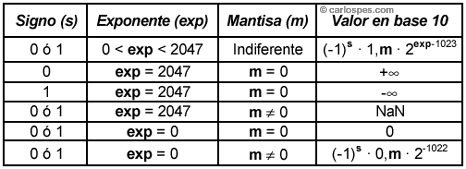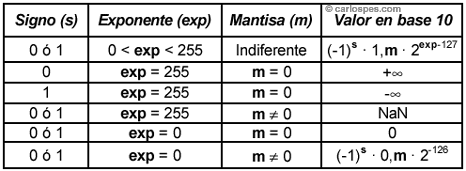

**Biografia:**

[https://es.wikipedia.org/wiki/IEEE_coma_flotante](https://es.wikipedia.org/wiki/IEEE_coma_flotante)

[https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/](https://blogs.mathworks.com/cleve/2014/07/07/floating-point-numbers/)

[https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/](https://blogs.mathworks.com/cleve/2014/07/21/floating-point-denormals-insignificant-but-controversial-2/)

# Exercici2

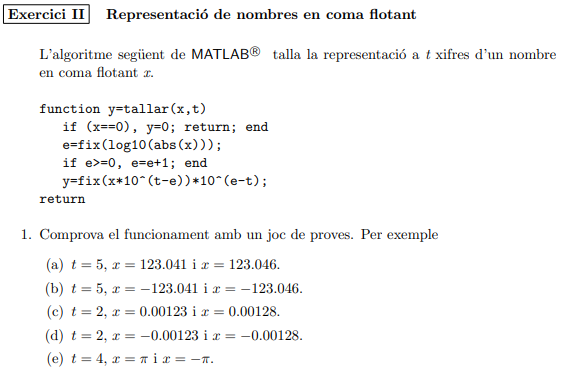

**a)**

format compact
format long
t = 5;
x = 123.051;
ya = tallar(x,t)
x = 123.046;
ya = tallar(x,t)

**b)**

t = 5;
x = -123.041;
yb = tallar(x,t)
x = -123.046;
yb = tallar(x,t)

**c)**

t = 2;
x = 0.00123;
yc = tallar(x,t)
x = 0.00128;
yc = tallar(x,t)

**d)**

t = 2;
x = -0.00123;
yd = tallar(x,t)
x = -0.00128;
yd = tallar(x,t)

**e)**

t = 4;
x = pi;
ye = tallar(x,t)
x = -pi;
ye = tallar(x,t)

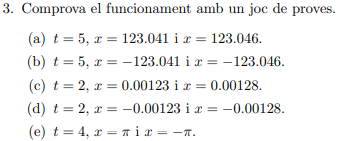

t = 5;
x = 123.051;
ya = redondear(x,t)
x = 123.046;
ya = redondear(x,t)

**b)**

t = 5;
x = -123.041;
yb = redondear(x,t)
x = -123.046;
yb = redondear(x,t)

**c)**

t = 2;
x = 0.00123;
yc = redondear(x,t)
x = 0.00128;
yc = redondear(x,t)

**d)**

t = 2;
x = -0.00123;
yd = redondear(x,t)
x = -0.00128;
yd = redondear(x,t)

**e)**

t = 4;
x = pi;
ye = redondear(x,t)
x = -pi;
ye = redondear(x,t)

# Exercici 3

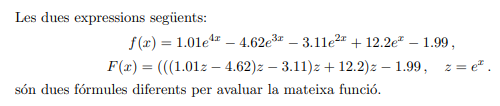

e = exp(1);
f_original = @(x) 1.01*e^(4*x)-4.62*e^(3*x)-3.11*e^(2*x)+12.2*e^x-1.99

f = @(x,t)redondear(1.01*redondear(e^(4*x),t),t)-redondear(4.62*redondear(e^(3*x),t),t)-redondear(3.11*redondear(e^(2*x),t),t)+redondear(12.2*(e^x),t)-1.99;

F = @(x,t)redondear(redondear(redondear(redondear(redondear((redondear(redondear(redondear(1.01*redondear(e^x,t),t)-4.62,t)*redondear(e^x,t),t)-3.11),t)*redondear(e^x,t),t)+12.2,t)*redondear(e^x,t),t)-1.99,t)

f1 = f(1.53,3)
F1 = F(1.53,3)
f1_original = f_original(1.53)

f2 = f(0.925,4)
F2 = F(0.925,4)
f2_original = f_original(0.925)

errorf1 = abs(f1_original-f1)/abs(f1_original)*100
errorF1 = abs(f1_original-F1)/abs(f1_original)*100

errorf2 = abs(f2_original-f2)/abs(f2_original)*100
errorF2 = abs(f2_original-F2)/abs(f2_original)*100

## Conclusiones

Como podemos observar  a la hora de realizar la aritmética con redondeo nos da diferentes valores aunque las funciones sean las mismas. El motivo principal es porque la función F(X) solo requiere hacer n multiplicaciones sobre el factor e^(x). En contra posición la función f(x) realiza n multiplicaciones también pero sobre factores como e^(4x),e^(3x),etc.

Provocando la minimización del  número de multiplicaciones que es lo más deseable ya que son inestables.

En definitiva F(x) es lo que se obtiene tras realizar el algoritmo de Horner sobre f(x).

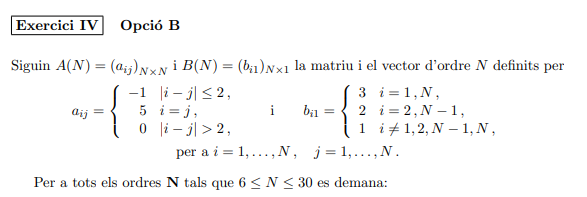

table = [];
for N = 6:30
    [A, b] = data_exercise_4(N);
    table = [table; N det(A) cond(A) isequal(A,A')];
end
table = array2table(table,'VariableNames',{'N','Determinante', 'Condiciones', 'Simetria'})

table = 25×4 table
    N     Determinante    Condiciones    Simetria
    __    ____________    ___________    ________

     6           9313       3.7413          1    
     7          40920       4.1779          1    
     8     1.7971e+05       4.5483          1    
     9      7.891e+05       4.8915          1    
    10     3.4645e+06       5.1419          1    
    11     1.5211e+07       5.4048          1    
    12     6.6779e+07       5.5974          1    
    13     2.9318e+08       5.7765          1    
    14     1.2871e+09       5.9272          1    
    15     5.6509e+09       6.0506          1    
    16     2.4809e+10       6.1701          1    
    17     1.0892e+11       6.2604          1    
    18     4.7817e+11       6.3527          1    
    19     2.0993e+12        6.426          1    
    20     9.2165e+12       6.4929          

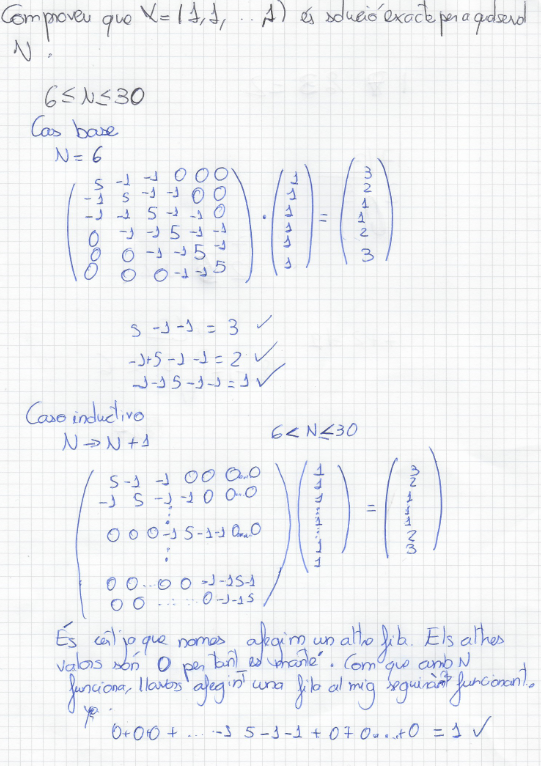

for N = 6:30
     [A, b] = data_exercise_4(N);
     [x] = eliminacionGaussiana(A,b);
     r = ones(size(b))-x;
end

x =        1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


x =        1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       
       1       


## **Conclusiones**

El beneficio que obtenemos de usar la eliminación Gaussiana para la matriz en este caso en concreto es que en el paso k del método Gaussiana solo tenemos que restar el pívot k a 2 filas que son la fila k+1 y la fila k+2.Eso es porque ya se encuentran todas las demás  a 0. 

El mètodo de Gauss és numèricamente estable y no hace falta intercambiar filas y columnas ya que la matriz A es diagonal dominante, simetrica y definida positiva.

for N = 6:30
     [A, b] = data_exercise_4(N);
     [x] = factorizacionQR(A,b);
     r = ones(size(b))-x;
end

## **Conclusiones**

Es un algoritmo bastante costoso para la resolución de sistemas de equaciones. Para este caso es el menos inconveniente.

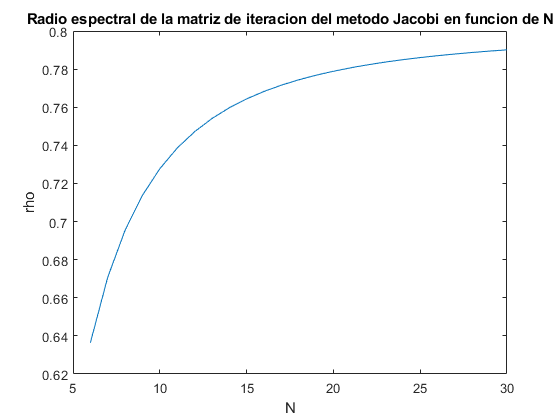

for N = 6:30
    [A, b] = data_exercise_4(N);
    D=diag(diag(A));
    d=diag(1 ./diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    Bj=-d*(A-D);
    d=inv(L+D);
    Bgs=-d*U;
    
    %Radio espectral
    rhoJ(N-5)=max(abs(eig(Bj)));
    rhoGs(N-5)=max(abs(eig(Bgs)));

    simetrica(N-5) = isequal(A,A');
    try chol(A);     
        definida_positiva(N-5) = true;
    catch ME
        definida_positiva(N-5) = false;
    end
end
plot(6:30, rhoJ), title('Radio espectral de la matriz de iteracion del metodo Jacobi en funcion de N')
xlabel('N'), ylabel('rho')

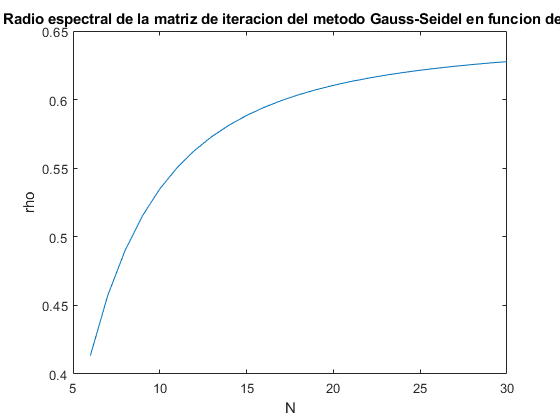

plot(6:30, rhoGs), title('Radio espectral de la matriz de iteracion del metodo Gauss-Seidel en funcion de N')
xlabel('N'), ylabel('rho')

## **Conclusiones**

# Teorema Ostrowski y Reich

**Comprovació simetrica**

isequal(simetrica,logical(ones(1,25)))

ans = logical
   1


**Comprovació definida positiva**

isequal(definida_positiva,logical(ones(1,25)))

ans = logical
   1


Como podemos observar A siempre cumple la condición de simetría, la condicion de tridiagonalidad por bloques y siempre esta definida positivamente.

Tambien cumple estas condicion:

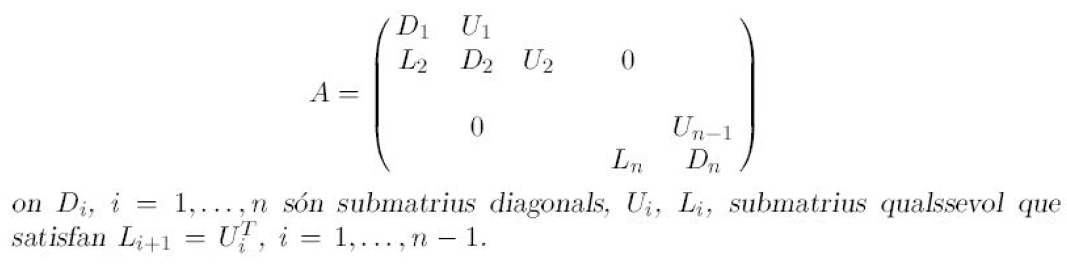

A partir de todas estas comprovaciones podemos decir que cumple todas las precondiciones necesarias para aplicar el teorema Ostrowski y Reich.

Como podemos observar en la gráfica, se cumple la poscondición de que la raíz del radio espectral de la matriz de iteración Gaussiana-Seidel es igual a la matriz de iteración de Jacobi.

Respecto a la convergencia podemos observar en la grafica que en ningún momento diverge ya que no supera el radio espectral nunca 1. También lo podemos observar a continuación.

rhoJ(rhoJ>=1) 


ans =

  1×0 empty double row vector



rhoGs(rhoGs>=1)


ans =

  1×0 empty double row vector



**Radios SOR - Jacobi y Radios SOR - Gauss-Seidel con matriz tamaño 20**

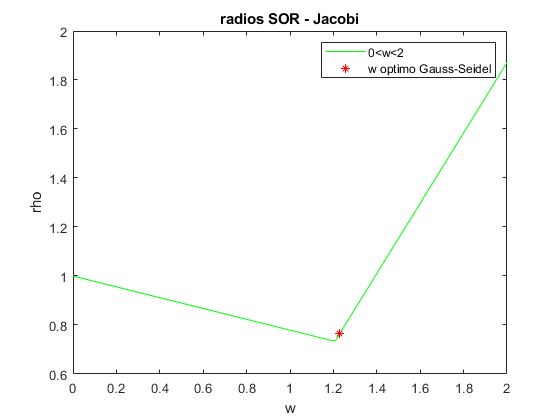

[A, b] = data_exercise_4(20);
radioSOR_Jacobi_Plot(A);
[woj rhoJ] = w_optima_Jacobi(A);
hold on
plot(woj,rhoJ,'*r','DisplayName','w optimo Gauss-Seidel')
hold off

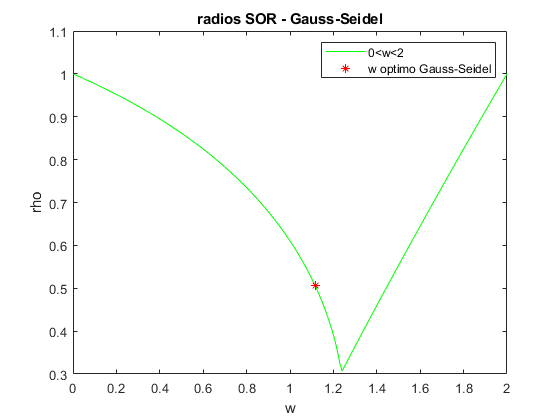

radioSOR_Gauss_Seidel_Plot(A);
[wogs ,rhoGS] = w_optima_Gauss_Seidel(A);
hold on
plot(wogs,rhoGS,'*r','DisplayName','w optimo Gauss-Seidel')
hold off

**Relacion tamaño de la matriz numero de iteraciones**

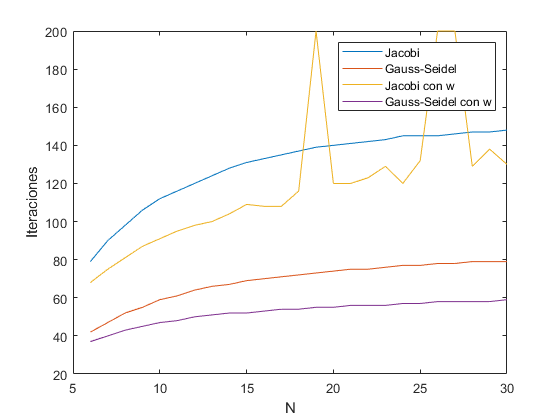

for N = 6:30
    [A, b] = data_exercise_4(N);
    %Metodo Jacobi
    [xj , i_Jacobi] = metodoJacobi(A,b,200);
    iteraciones_Jacobi(N-5) = i_Jacobi;
    
    %Metodo Gauss Seidel
    [xgs, i_Gauss_Seidel] = metodoGauss_Seidel(A,b,200);
    iteraciones_Gauss_Seidel(N-5) = i_Gauss_Seidel;
    
    %Metodo de Jacobi con w
    [woj rhoJ] = w_optima_Jacobi(A);
    [xj, i_Jacobi_con_w] = metodoJacobi_con_w(A,b,woj,200);
    iteraciones_Jacobi_con_w(N-5) = i_Jacobi_con_w;
    
    %Metodo de Gauss-Seidel con w
    [wogs ,rhoGS] = w_optima_Gauss_Seidel(A);
    [xgs, i_Gauss_Seidel_con_w] = metodoGauss_Seidel_con_w(A,b,wogs,200);
    iteraciones_Gauss_Seidel_con_w(N-5) = i_Gauss_Seidel_con_w;
    
    %desviaciones de la solucion
    r = ones(size(xj))-xj;
    r = ones(size(xgs))-xgs;
    r = ones(size(woj))-woj;
    r = ones(size(wogs))-wogs;
end


plot(6:30,iteraciones_Jacobi),xlabel('N'),ylabel('Iteraciones')
legend('Jacobi');
hold on
plot(6:30,iteraciones_Gauss_Seidel,'DisplayName','Gauss-Seidel')
plot(6:30,iteraciones_Jacobi_con_w,'DisplayName','Jacobi con w')
plot(6:30, iteraciones_Gauss_Seidel_con_w,'DisplayName','Gauss-Seidel con w')
hold off

## **Conclusiones**

Como tanto el método de Jacobi como el de Gauss-Seidel es convergente, el método de Gauss-Seidel es más rápido. Lo podemos observar a partir de la grafica, ya que acaba Gauss-Seidel encuentra la solución con menos iteraciones.

En contraposición podemos observar que Gauss-Seidel con coeficiente de relajación optimo es mucho más rápido que Jacobi con coeficiente de relajación optimo ya que encuentra la solución con menos iteraciones.

Como podemos observar en la grafica podemos observar como Jacobi con w no llega a veces a obtener la solución exacta antes de las 200 iteraciones eso se debe a que intenta converger a la solución pero avanza muy lentamente.

Finalmente podemos decir que el algoritmo para resolver este tipo de problemas es Gauss-Seidel con coeficiente de relajación, ya que como máximo se realizan 60 iteraciones.

# Función cortar

function y=tallar(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = fix(x*10^(t-e))*10^(e-t);
    return
end

# Función redondear

function y=redondear(x,t)
    if x==0
        y = 0;
        return
    end 
    e=fix(log10(abs(x)));
    if e>=0 
        e=e+1;
    end 
    y = round(x*10^(t-e))*10^(e-t);
    return
end

# FORWARD. Forward elimination

function x = forward(L,x)
% FORWARD. Forward elimination.
% For lower triangular L, x = forward(L,b) solves L*x = b.
[n,n] = size(L);
x(1) = x(1)/L(1,1);
for k = 2:n
   j = 1:k-1;
   x(k) = (x(k) - L(k,j)*x(j))/L(k,k);
end
end

% ------------------------------

# BACKSUBS.  Back substitution.

function x = backsubs(U,x)
% BACKSUBS.  Back substitution.
% For upper triangular U, x = backsubs(U,b) solves U*x = b.
[n,n] = size(U);
x(n) = x(n)/U(n,n);
for k = n-1:-1:1
   j = k+1:n;
   x(k) = (x(k) - U(k,j)*x(j))/U(k,k);
end
end


# Creación de matrices exercicio 4

function [A, b] = data_exercise_4(N)
    A = zeros(N);
    for i = 1:N
        for j = 1:N
            if abs(i-j) <= 2 && i ~= j
                A(i,j) = -1;
            elseif  i == j
                A(i,j) = 5;
            else
                A(i,j) = 0;
            end
        end
    end
    b = ones(1,N)*3;
    b(2) = 2;
    b(N-1) = 2;
    b(3:N-2) = 1;
    b = b';
end

# Eliminación Gaussiana (Metode directo)

function [x] = eliminacionGaussiana(A,b) 
    [h w] = size(A);
    U = [A b];
    for i = 1:h
        %%Pivot trivial
        if U(i,i) == 0
            for k = (i+1):h
                if (U(k,i) ~= 0)
                    aux = U(k,:);
                    U(k,:) = U(i,:);
                    U(i,:) = aux;
                end
            end
        end
        
        U(i,:) = U(i,:)/U(i,i);
        if (U(i,i) < 0)
            U(i,:) = U(i,:)*-1;
        end
        for j = (i+1):h
                U(j,:) = U(j,:)- U(j,i)*U(i,:);
        end
    end
    x = backsubs(U(:, 1:w), U(:, w+1 ))
end

# Factorización QR (Metode directo)

function [x] = factorizacionQR(A,b)
    %Q*R = A
    [Q,R] = qr(A);
    %1) Rx = Q'b
    x = backsubs(R,Q'*b);
    %comprobar que el residuo es 0
    r = b -A*x;
end

# Radio SOR - Jacobi (Plot)

function radioSOR_Jacobi_Plot(A)
    D=diag(diag(A));
    d=diag(1 ./diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    w = 0:0.01:2; n=length(w);
    for k=1:n
        Bwj=d*((1-w(k))*D-w(k)*(L+U));
        rhoWJ(k)=max(abs(eig(Bwj)));
    end
    [w;rhoWJ]';
    plot(w,rhoWJ,'g'), title('radios SOR - Jacobi'), xlabel('w'), ylabel('rho'), legend('0<w<2')
end

# Radio SOR - Gauss-Seidel (Plot)

function radioSOR_Gauss_Seidel_Plot(A)
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    w = 0:0.01:2; n=length(w);
    for k=1:n
        d = inv(w(k)*L+D);
        Bwgs=d*((1-w(k))*D-w(k)*(U));
        rhoWGS(k)=max(abs(eig(Bwgs)));
    end
    [w;rhoWGS]';
    plot(w,rhoWGS,'g'), title('radios SOR - Gauss-Seidel'), xlabel('w'), ylabel('rho'), legend('0<w<2')
end

# Metodo Jacobi

function [xj, i] = metodoJacobi(A,b,n)
    D=diag(diag(A));
    d=diag(1 ./diag(A));
    Bj=-d*(A-D);
    rhoJ=max(abs(eig(Bj)));
    cj=d*b;
    if (rhoJ >= 1) 
        display('mètode de JACOBI divergent');
    else
    % Iteracions del mètode Jacobi
        xj=zeros(size(b));
        i = 1;
        control = 2;
        while i<=n && control >eps
             new=Bj*xj+cj;
             rj(i)=norm(A*new-b);
             control=norm(new-xj)/norm(new);
             xj=new;
             i = i +1;
        end
        i = i -1;
    end
end

# Metodo de Gauss-Seidel

function [xgs, i] = metodoGauss_Seidel(A,b,n)
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    d=inv(L+D);
    Bgs=-d*U;
    rhoGS=max(abs(eig(Bgs)));
    cgs=d*b;
    if (rhoGS >= 1 && false) 
        display('mètode de Gauss-Seidel divergent');
    else
    % Iteracions del mètode Gauss-Seidel
        B=Bgs; c=cgs;
        xgs=zeros(size(b));
        i = 1;
        control = 2;
        while i<=n && control >eps
            new=B*xgs+c;
            rgs(i)=norm(A*new-b);
            control=norm(new-xgs)/norm(new);
            xgs=new;    
            i = i +1;
        end
        i = i-1;
    end
end

# w optima con Jacobi

function [wo, rhoWJ] = w_optima_Jacobi(A)
    D=diag(diag(A));
    d=diag(1 ./diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    Bj=-d*(A-D);
    rhoJ=max(abs(eig(Bj)));
    wo = 2/(1+sqrt(1-(rhoJ^2)));
    %Obtener el radio espectral del coeficient espectral optim
    Bwj=d*((1-wo)*D-wo*(L+U));
    rhoWJ =max(abs(eig(Bwj)));
end

# Metodo de Jacobi con w

function [xjw, i] = metodoJacobi_con_w(A,b,w,n)    
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    d=inv(D);
    Bwj=d*((1-w)*D-w*(L+U));
    cwj = d*w*b;
    xjw=zeros(size(b));
    i = 1;
    control = 2;
    while i<=n && control >eps 
        new=Bwj*xjw+cwj;
        rjw(i)=norm(A*new-b);
        control=norm(new-xjw)/norm(new);
        xjw=new;
        i = i +1;
    end
    i = i-1;
end

# w optima con Gauss-Seidel

function [wo, rhoGS] = w_optima_Gauss_Seidel(A)
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    d=inv(L+D);
    Bgs=-d*U;
    rhoGS=max(abs(eig(Bgs)));
    wo = 2/(1+sqrt(1-(rhoGS^2)));
    %Obtener el radio espectral del coeficient espectral optim
    d = inv(wo*L+D);
    Bwgs=d*((1-wo)*D-wo*(U));
    rhoGS=max(abs(eig(Bwgs)));
end

# Metodo de Gauss-Seidel con w

function [xgsw,i] = metodoGauss_Seidel_con_w(A,b,w,n)
    D=diag(diag(A));
    L=tril(A,-1);
    U=triu(A,1);
    d=inv(D+w*L);
    Bw=d*((1-w)*D-w*U);
    cw=d*w*b;
    xgsw=zeros(size(b));
    i = 1;
    control = 2;
    while i<=n && control > eps
        new=Bw*xgsw+cw;
        rgsw(i)=norm(A*new-b);
        control=norm(new-xgsw)/norm(new);
        xgsw=new;  
        i = i+1;
    end
    i = i -1;
end